1. Fit a cubic polynomial to the following data by extending the system of equations on lecture slide 3, then calculate the standard error and correlation coefficient. Graph the data and your fitting equation.

x = [3 4 5 7 8 9 11 12]

x =      3     4     5     7     8     9    11    12


y = [1.6 3.6 4.4 3.4 2.2 2.8 3.8 4.6]

y =     1.6000    3.6000    4.4000    3.4000    2.2000    2.8000    3.8000    4.6000


close all
plot(x, y, 'o', 'MarkerEdgeColor', 'r')
hold on

element = polyfit(x, y, 3);
disp(element);

    0.0467   -1.0412    7.1438  -11.4887



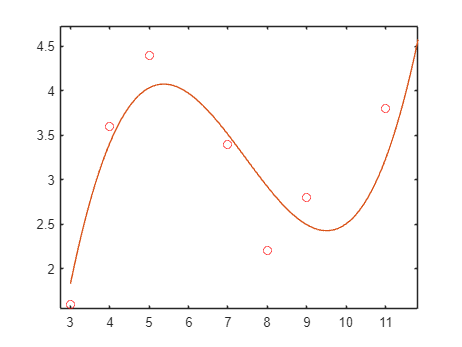

fit_line = polyval(element, X);
plot(X, fit_line);
hold off


% find correlation coefficient:
sr_power = (y - element(4) - element(3).*x - element(2).*(x.^2) - element(1).*(x.^3)).^2

sr_power =     0.0539    0.0344    0.1334    0.0118    0.5223    0.0932    0.3215    0.1292


Sr = sum(sr_power);
mean_y = mean(y);
st_power = (y - mean_y).^2;
St = sum(st_power);
X = linspace(3, 12);
r = sqrt((St - Sr)./St);

disp(r);

    0.9105



2. Do the same as in the Question 1 but using the general Z-matrix formulation given on slides 21-25. You should get the same result if you have done it correctly.

x = [3 4 5 7 8 9 11 12]';
y = [1.6 3.6 4.4 3.4 2.2 2.8 3.8 4.6]';

z = [ones(size(x)) x x.^2 x.^3];
disp(z);

ans = (z'*z)\(z'*y)
disp(ans)

3. Calculate the standard error for the 2 power equation models from Example 6 in the lecture notes and decide if one equation is better than the other or not.

x = [10 20 30 40 50 60 70 80];
y = [25 70 380 550 610 1220 830 1450];

% nonlinear regression method
A = fminsearch(@fit_power,[1,1],[],x,y)
F = @(v) A(1)*v.^(A(2));
close all
plot(x,y,'or','Markersize',6,'Markerfacecolor','r')
hold on
fplot(F,[10,80])

% linear regression method
a = polyfit(log10(x), log10(y), 1)
disp(a);
s = 10.^a(2);
t = a(1);

linear_func = @(x) s*(x.^(t));
X = linspace(10, 80);
plot(X, linear_func(X))
hold off

% find the standard error of non-linear
Sr1 = sum((y - A(1)*x.^(A(2))).^2);
Sxy1 = sqrt(Sr1./(8-(1+1)));
disp(Sxy1);

% find the standard error of the lienar
Sr2 = sum((y - s*(x.^(t))).^2);
Sxy2 = sqrt(Sr2./(8-(1+1)));
disp(Sxy2);

4. For the following data use polynomial regression to get an equation that predicts the dissolved oxygen concentration as a function of temperature for the case where the chloride concentration is 0. Graph the data and your fitting equation.

T = [0 5 10 15 20 25 30];
c0 = [14.6 12.8 11.3 10.1 9.09 8.26 7.56];
a = polyfit(T, c0, 2);
disp(a);

    0.0044   -0.3634   14.5519




X = linspace(0, 30);
y = polyval(a, X);

polyReg = @(x) 14.5519 - 0.3634.*x + 0.0044.*(x^2);
disp(polyReg(5));

   12.8449



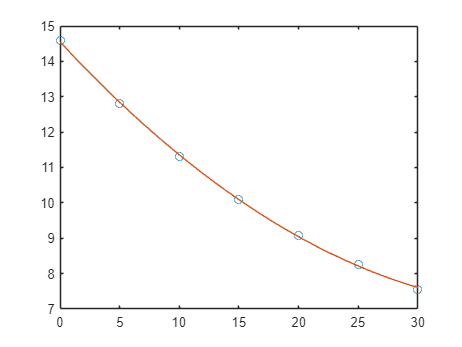


close all
plot(T, c0, 'o');
hold on
plot(X, y);
hold off

5. For the data from Question 4 use multiple linear regression to predict the dissolved oxygen concentration as a function of temperature and chloride concentration (Hint: Make a new table of values). Plot the data and your equation then use your equation to predict the dissolved oxygen concentration when the chloride concentration is 15 g/L and temperature is 12oC. 

% Step 1: Domain
tval = 0:5:30;
t = [tval tval tval]';
c = [0 0 0 0 0 0 0 10 10 10 10 10 10 10 20 20 20 20 20 20 20]';
y = [14.6 12.8 11.3 10.1 9.09 8.26 7.56 12.9 11.3 10.1 9.03 8.17 7.46 6.85 11.4 10.3 8.96 8.08 7.35 6.73 6.20]';

% Step 2: Solve for a to create fitted function
z = [ones(size(t)) t c];  % เป็น 2 ตัวแปร
a = (z'*z)\(z'*y);

% Step 3: Create fitted function
fitted_func = @(temp, concent) a(1) + a(2).*temp + a(3).*concent;

% Step 4: Eval the value
fprintf('Oxygen estimated to be %f\n', fitted_func(12, 15));

Oxygen estimated to be 9.533357


6. Use multiple linear regression to fit the following data. Also calculate the standard error and correlation coefficient.

x1 = [0 1 1 2 2 3 3 4 4];
x2 = [0 1 2 1 2 1 2 1 2];
y = [15.1 17.9 12.7 25.6 20.5 35.1 29.7 45.4 40.2];
n = 9;

sum_x1 = sum(x1);
sum_x2 = sum(x2);
sum_y = sum(y);
power_x1 = sum(x1.^2);
power_x2 = sum(x2.^2);
x1x2 = sum(x1.*x2);
x1y = sum(x1.*y);
x2y = sum(x2.*y);

b = [n  sum_x1 sum_x2; sum_x1 power_x1 x1x2; sum_x2 x1x2 power_x2];
A = [sum_y; x1y; x2y];
% a = inv(b)*A; % don't forget that this is not polyfit so the value in 'a' array will be [a0 a1 a2]
a = b\A;
disp(a);
disp(a(3));

Sr = sum((y - a(1) - a(2)*x1 - a(3)*x2).^2);
St = sum((y - mean(y)).^2);
standErr = sqrt(Sr/(n-(2+1))); % for multiple linear regression will define m as the number of predictor variables in this case we have x1 x2 so m = 2 
r = sqrt((St - Sr)/St);
disp(standErr);
disp(r);

% for Q6 you can also do this:
% Step 1: Domain
x1 = [0 1 1 2 2 3 3 4 4]'; % don't forget to put ' after the bracket
x2 = [0 1 2 1 2 1 2 1 2]';
y = [15.1 17.9 12.7 25.6 20.5 35.1 29.7 45.4 40.2]';
n = length(x1);
degree = 2;

% Step 2: Create fitted function
z = [ones(size(x1)) x1 x2];  % เป็น 2 ตัวแปร
a = (z'*z)\(z'*y);
disp('a =');

a =


disp(a);

   14.4609
    9.0252
   -5.7043




% Step 3: Calculate Std.Err and Correlation Coef.

% Correlation Coef. => r.^2 = st - sr / st
ybar = mean(y);
st = sum((y - ybar).^2);
sr =  sum((y - a(1) - a(2).*x1 - a(3).*x2).^2);
r2 = sqrt((st - sr) ./ st);

% Standard Error => sqrt( sr / n - (m+1) )
% n = number of data points
% m = degree of a polynomial
syx = sqrt(sr ./ (n - (degree + 1)));
fprintf("r = %f\n", r2);

r = 0.997759


fprintf("Syx = %f\n", syx);

Syx = 0.888787


7. Fluid flow was measured in concrete circular pipes of various sizes and angles (slopes). Use multiple linear regression (logarithm method) to fit the following equation to the data.

D = [0.3 0.6 0.9 0.3 0.6 0.9 0.3 0.6 0.9];
S = [0.001 0.001 0.001 0.01 0.01 0.01 0.05 0.05 0.05];
Q = [0.04 0.24 0.69 0.13 0.82 2.38 0.31 1.95 5.66];
n = 9

x1 = log10(D);
x2 = log10(S);
y = log10(Q);
sum_x1 = sum(x1);
sum_x2 = sum(x2);
sum_y = sum(y);
power_x1 = sum(x1.^2);
power_x2 = sum(x2.^2);
x1x2 = sum(x1.*x2);
x1y = sum(x1.*y);
x2y = sum(x2.*y);

b = [n  sum_x1 sum_x2; sum_x1 power_x1 x1x2; sum_x2 x1x2 power_x2];
A = [sum_y; x1y; x2y];
a = inv(b)*A;
disp(a);
a0 = 10^a(1);
a1 = a(2);
a2 = a(3);
disp(a0)

8. Three disease-carrying organisms decay exponentially in seawater according to the following model equation. Use general least squares to estimate the coefficients and estimate the initial concentration of each organism from the following measurements. 

xnorm = [0.5 1 2 3 4 5 6 7 9];
ynorm = [6 4.4 3.2 2.7 2 1.9 1.7 1.4 1.1];
x = [0.5 1 2 3 4 5 6 7 9]';
y = [6 4.4 3.2 2.7 2 1.9 1.7 1.4 1.1]';

z = [exp(-1.5.*x) exp(-0.3.*x) exp(-0.05.*x)]; 
% the reason why we don't make the first column to ones because
% if we look at the equation it the z0 = A not 1
a = (z'*z)\(z'*y);
disp(a);

    4.1375
    2.8959
    1.5349




X = linspace(0.5, 9);
Y = @(x) a(1).*exp(-1.5.*x) + a(2).*exp(-0.3.*x) + a(3).*exp(-0.05.*x)

Y = function_handle with value:
    @(x)a(1).*exp(-1.5.*x)+a(2).*exp(-0.3.*x)+a(3).*exp(-0.05.*x)


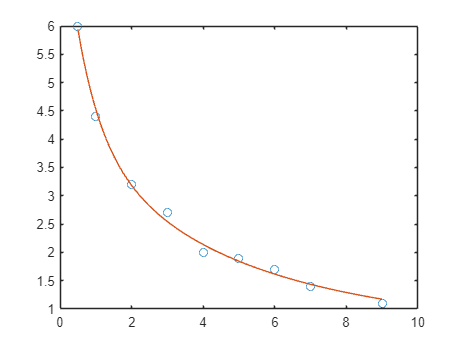

close all
plot(xnorm, ynorm, 'o');
hold on
plot(X, Y(X));

9. Use nonlinear regression to estimate α4 and β4 based on the following data. Develop a plot of your fit along with the data. 

x = [0.1 0.2 0.4 0.6 0.9 1.3 1.5 1.7 1.8];
y = [0.75 1.25 1.45 1.25 0.85 0.55 0.35 0.28 0.18];

% nonlinear regression method
A = fminsearch(@fit_power2,[1,1],[],x,y)
F = @(v) A(1).*v.*exp(A(2).*v);
close all
plot(x,y,'or','Markersize',6,'Markerfacecolor','r')
hold on
fplot(F,[0.1,1.8])

10. Use Matlab’s symbolic toolbox to factorise the following polynomial:

syms x y
poly = x^3 + 3*x^2 - x - 3;
fac = solve(poly, x);
disp(fac);
factored_polynomial = factor(poly);
disp(factored_polynomial);

11. . Use Matlab’s symbolic toolbox to find the 3rd order Taylor series expansion of the following function about the point x = –1.

syms x;

y = exp(-3*x^2) * sin(x^7 - 5*x^2);
taylor_expansion = taylor(y, x, -1, 'Order', 3);
disp(taylor_expansion);

12. Use Matlab’s symbolic toolbox to solve the following system of equations for the variables x and y.

syms x y;
eq1 = 3*x - y == 12;
eq2 = x + 3*y == -7;
solutions = solve([eq1, eq2], [x, y]);
disp(solutions)

13. Use Matlab’s symbolic toolbox to differentiate the following function.

function Sr = fit_power(a,x_data,y_data)
% a = [alpha, beta]
F_power = a(1)*x_data.^a(2);
Sr = sum((y_data - F_power).^2);
end

function Sr = fit_power2(a,x_data,y_data)
% a = [alpha, beta]
F_power = a(1).*x_data.*exp(a(2).*x_data);
Sr = sum((y_data - F_power).^2);
end